# 1.1

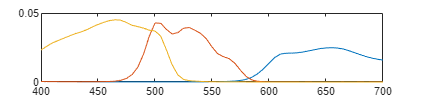

n = length(Ad);
x = linspace(400,700,n);
plot(x,Ad)

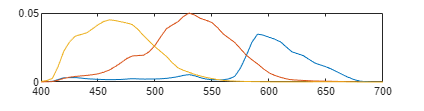

plot(x,Ad2)

Ad & Ad2 looks similar but not exact. They will definitly give different outputs. We think Ad2 will give a higher contrast image.

Answer: No.

# 1.2

## Camera 1

e = CIED65 .* chips20;

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad'*e';

showRGB(d')

## Camera 2

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad2'*e';

showRGB(d')

# 2.1

% Taking a photo of a  completely white image
ref1 = Ad'*ones(1,61)';
ref2 = Ad2'*ones(1,61)';

% Computing the normalization values
cf1 = ones(3,1) ./ ref1

cf1 =     2.1574
    1.7711
    1.1649


cf2 = ones(3,1) ./ ref2

cf2 =     2.1161
    1.1433
    1.3476


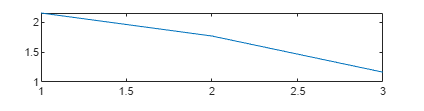


plot(cf1)

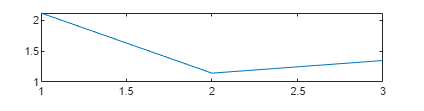

plot(cf2)

# 2.2

% Calculating RAW RGB values for both cameras under the same light source
e = CIED65 .* chips20;

RAW_C1_CIED65 = Ad'*e';
RAW_C2_CIED65 = Ad2'*e';

% Calibrating the values
CAL_DATA_C1_CIED65 = RAW_C1_CIED65 .* cf1;
CAL_DATA_C2_CIED65 = RAW_C2_CIED65 .* cf2;
 
showRGB(CAL_DATA_C1_CIED65')
showRGB(CAL_DATA_C2_CIED65')

# 2.3

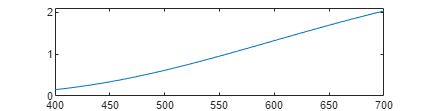

n = length(CIEA);
x = linspace(400,700,n);
plot(x,CIEA)
ylim([0,2.1])

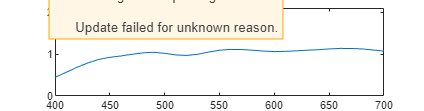

plot(x,CIEB)
ylim([0,2.1])

# 2.4

e = CIED65 .* chips20;
e2 = CIEA .* chips20;

% 1 Taking a picture of 20 surfaces
d1_raw_65 = Ad'*e';
d1_raw_CIEA = Ad'*e2';

% 2 Taking a picture of a completely white surface (ones)
d1_raw_65_v = Ad'*CIED65';
d1_raw_CIEA_v = Ad'*CIEA';

% 3 Calibration factors, same!
cf1 = ones(3,1) ./ d1_raw_65_v;
cf2 = ones(3,1) ./ d1_raw_CIEA_v;

% 1 multiplied with calibration factors
RGB_cal_CIE65 = d1_raw_65 .* cf1;
RGB_cal_CIEA = d1_raw_CIEA .* cf2;

showRGB(d1_raw_65')
showRGB(d1_raw_CIEA')

showRGB(RGB_cal_CIE65')
showRGB(RGB_cal_CIEA')

# 2.5

% d = Ad' * (chips20 .* CIEA)'
e = CIED65 .* chips20;
e2 = CIEA .* chips20;

% 1 Taking a picture of 20 surfaces
d1_raw_65 = Ad'*e';
d1_raw_CIEA = Ad'*e2';

% Calculating the reference image (taking a picture of white surface)
ref1 = Ad'*CIED65';
ref2 = Ad'*CIEA';

% Normalizing and calculating the calibration factors 
cf = ones(3,1) ./ ref1;
cf2 = ones(3,1) ./ ref2;

% Scaling
RGB_cal_D65 = d1_raw_65 .* cf;
RGB_cal_A = d1_raw_CIEA .* cf2;

showRGB(RGB_cal_D65')
showRGB(RGB_cal_A')

# 3.1

% Calculating the exact xyz values from RBG, our "correct" values
k = 100 ./ (CIED65 * xyz(:,2))

xyzValuesFromSpectra = xyz'*( CIED65 .* chips20 )' * k


# 3.2

Approx XYZ values in different ways 3.2, 3.4, 3.5

CAL_DATA_C1_CIED65_XYZ = M_XYZ2RGB \ CAL_DATA_C1_CIED65
C_XYZ = CAL_DATA_C1_CIED65_XYZ
REF_XYZ = xyzValuesFromSpectra

[L, a, b] =  xyz2lab(C_XYZ(1,:)', C_XYZ(2,:)', C_XYZ(3,:)');

C_LAB = zeros(3,20);
C_LAB(1,:) = L;
C_LAB(2,:) = a;
C_LAB(3,:) = b;

[L, a, b] =  xyz2lab(REF_XYZ(1,:)', REF_XYZ(2,:)', REF_XYZ(3,:)');

REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;

dE = euclidean_distance_lab(REF_LAB, C_LAB)

mean(dE)
max(dE)

# 3.3

plot(x, Ad)
plot(x, xyz)

# 3.4

D = CAL_DATA_C1_CIED65'
C = xyzValuesFromSpectra'
A = pinv(D)*C

xyz_aprox = D * A

[L, a, b] =  xyz2lab(xyz_aprox(:,1), xyz_aprox(:,2), xyz_aprox(:,3));

APROX_LAB = zeros(3,20);
APROX_LAB(1,:) = L;
APROX_LAB(2,:) = a;
APROX_LAB(3,:) = b;

dE = euclidean_distance_lab(APROX_LAB, REF_LAB)
mean(dE)
max(dE)


# 3.5

D = CAL_DATA_C1_CIED65'
C = xyzValuesFromSpectra'
A11 = Optimize_poly(D', C')
xyz_aprox_a11 = Polynomial_regression(D', A11)

[L, a, b] =  xyz2lab(xyz_aprox_a11(1,:)', xyz_aprox_a11(2,:)', xyz_aprox_a11(3,:)');

APROX_LAB = zeros(3,20);
APROX_LAB(1,:) = L;
APROX_LAB(2,:) = a;
APROX_LAB(3,:) = b;

dE = euclidean_distance_lab(APROX_LAB, REF_LAB)
mean(dE)
max(dE)

# # Functions

function dE = euclidean_distance_lab(V1, V2)
    arguments
        V1 (3,20) {mustBeNumeric, mustBeNumeric}
        V2 (3,20) {mustBeNumeric, mustBeNumeric}
    end
    L1 = V1(1,:);
    L2 = V2(1,:);

    a1 = V1(2,:);
    a2 = V2(2,:);

    b1 = V1(3,:);
    b2 = V2(3,:);

    dE = sqrt((L1-L2).^2 + (a1-a2).^2 + (b1-b2).^2);
end